## Q2 - part d | Output Error

clc; clear;

%%

load HW5_question2

u3 = Z3.u;
y3 = Z3.y;

u3_val = u3;%(601:end);
y3_val = y3;%(601:end);

u3 = u3(1:600);
y3 = y3(1:600);


%%

% System Z3 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System III Identification Begins:------------------------------\n")

>>> System III Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u3)*Ts-Ts;
t_val = 0:Ts:length(u3_val)*Ts-Ts;
N = length(y3);
N_val = length(y3_val);

data3 = iddata(y3,u3,Ts);


%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    try
        sys = oe(data3, [na nb nk]);
        oe_y_hat_3 = lsim(sys, u3, t);
    catch
        break
    end

    [r2_oe, mse_oe] = rSQR(y3, oe_y_hat_3);

    error = y3 - oe_y_hat_3;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_oe, mse_oe, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_oe];
    MSEs = [MSEs; mse_oe];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.081631 | MSE=128.147675 | var=128.576263 | s_hat=76888.605097 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.973406 | MSE=3.710940 | var=3.735846 | s_hat=2226.564102 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.997642 | MSE=0.329021 | var=0.332345 | s_hat=197.412768 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.997730 | MSE=0.316735 | var=0.321015 | s_hat=190.040824 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.997767 | MSE=0.311633 | var=0.316915 | s_hat=186.979795 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.997771 | MSE=0.311054 | var=0.317402 | s_hat=186.632100 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.997789 | MSE=0.308561 | var=0.315932 | s_hat=185.136375 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.997857 | MSE=0.299073 | var=0.307267 | s_hat=179.444081 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.997792 | MSE=0.308169 | var=0.317700 | s_hat=184.901608 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.997095 | MSE=0.405294 | var=0.419270 | s_hat=243.176546 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.997781 | MSE=0.309570 | var=0.321352 | s_hat=185.741712 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.997802 | MSE=0.306657 | var=0.319435 | s_hat=183.994403 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.997793 | MSE=0.307974 | var=0.321924 | s_hat=184.784356 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.997815 | MSE=0.304908 | var=0.319833 | s_hat=182.944574 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.997831 | MSE=0.302638 | var=0.318566 | s_hat=181.582673 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.997829 | MSE=0.302923 | var=0.319989 | s_hat=181.753669 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.997776 | MSE=0.310368 | var=0.329012 | s_hat=186.220608 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.997818 | MSE=0.304528 | var=0.323966 | s_hat=182.716833 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.994546 | MSE=0.761032 | var=0.812490 | s_hat=456.619354 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.997121 | MSE=0.401713 | var=0.430407 | s_hat=241.027976 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.997854 | MSE=0.299473 | var=0.322014 | s_hat=179.683730 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.997742 | MSE=0.315138 | var=0.340077 | s_hat=189.083019 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.997813 | MSE=0.305132 | var=0.330468 | s_hat=183.079029 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.997774 | MSE=0.310575 | var=0.337582 | s_hat=186.345120 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.997906 | MSE=0.292186 | var=0.318748 | s_hat=175.311344 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.997786 | MSE=0.308901 | var=0.338212 | s_hat=185.340303 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.997783 | MSE=0.309320 | var=0.339912 | s_hat=185.591819 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.997911 | MSE=0.291499 | var=0.321506 | s_hat=174.899115 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.997901 | MSE=0.292824 | var=0.324160 | s_hat=175.694599 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.997943 | MSE=0.287040 | var=0.318933 | s_hat=172.224061 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.997952 | MSE=0.285744 | var=0.318674 | s_hat=171.446675 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.997982 | MSE=0.281628 | var=0.315256 | s_hat=168.977048 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.997959 | MSE=0.284741 | var=0.319933 | s_hat=170.844462 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.997969 | MSE=0.283391 | var=0.319614 | s_hat=170.034555 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.997942 | MSE=0.287194 | var=0.325126 | s_hat=172.316669 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.997981 | MSE=0.281722 | var=0.320139 | s_hat=169.033156 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.997969 | MSE=0.283439 | var=0.323314 | s_hat=170.063309 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.997951 | MSE=0.285896 | var=0.327362 | s_hat=171.537584 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.997954 | MSE=0.285473 | var=0.328130 | s_hat=171.283966 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.997887 | MSE=0.294880 | var=0.340246 | s_hat=176.927782 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.998038 | MSE=0.273731 | var=0.317063 | s_hat=164.238584 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.997822 | MSE=0.303927 | var=0.353404 | s_hat=182.356273 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.998034 | MSE=0.274381 | var=0.320290 | s_hat=164.628863 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.948373 | MSE=7.203984 | var=8.442169 | s_hat=4322.390326 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.997791 | MSE=0.308188 | var=0.362575 | s_hat=184.913031 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.994322 | MSE=0.792235 | var=0.935711 | s_hat=475.341044 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.997930 | MSE=0.288841 | var=0.342499 | s_hat=173.304628 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.997933 | MSE=0.288421 | var=0.343358 | s_hat=173.052592 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.998168 | MSE=0.255587 | var=0.305483 | s_hat=153.352461 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.996945 | MSE=0.426330 | var=0.511596 | s_hat=255.797805 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.997769 | MSE=0.311276 | var=0.375031 | s_hat=186.765564 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.997592 | MSE=0.335947 | var=0.406387 | s_hat=201.568022 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.997430 | MSE=0.358554 | var=0.435491 | s_hat=215.132340 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.998174 | MSE=0.254759 | var=0.310681 | s_hat=152.855117 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.998222 | MSE=0.248088 | var=0.303781 | s_hat=148.852838 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.997100 | MSE=0.404713 | var=0.497598 | s_hat=242.827703 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.998064 | MSE=0.270175 | var=0.333550 | s_hat=162.105196 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.998011 | MSE=0.277552 | var=0.344073 | s_hat=166.531452 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.995958 | MSE=0.564063 | var=0.702153 | s_hat=338.437940 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.997864 | MSE=0.298010 | var=0.372513 | s_hat=178.806038 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.996142 | MSE=0.538350 | var=0.675754 | s_hat=323.010273 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.998183 | MSE=0.253586 | var=0.319646 | s_hat=152.151557 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 55 


na = bestFitDegree;
nb = bestFitDegree;
nk = 1;
p = na+nb;

BestFitModel_3 = oe(data3, [na nb nk])

BestFitModel_3 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                     
                                                                                                          
  B(z) = 0.6374 z^-1 + 2.627 z^-2 + 5.379 z^-3 + 7.678 z^-4 + 8.304 z^-5 + 6.716 z^-6 + 3.693 z^-7        
          + 0.6321 z^-8 - 1.437 z^-9 - 2.376 z^-10 - 2.391 z^-11 - 1.477 z^-12 + 0.3626 z^-13             
          + 2.895 z^-14 + 5.592 z^-15 + 7.636 z^-16 + 8.599 z^-17 + 8.402 z^-18 + 7.087 z^-19             
          + 5.156 z^-20 + 3.25 z^-21 + 1.891 z^-22 + 1.335 z^-23 + 1.379 z^-24 + 1.436 z^-25              
          + 1.29 z^-26 + 1.242 z^-27 + 1.607 z^-28 + 2.47 z^-29 + 3.629 z^-30 + 4.677 z^-31 + 5.217 z^-32 
          + 4.958 z^-33 + 3.659 z^-34 + 1.635 z^-35 - 0.5891 z^-36 - 2.054 z^-37 - 2.151 z^-38            
          - 1.24 z^-39 + 0.1281 z^-40 + 1.197 z^-41 + 1.75 z^-42 + 2.203 z^-43 + 2.656 z^-44              
          + 2.779 z^

BestFit_y_hat_3 = lsim(BestFitModel_3, u3_val, t_val);
% [oe_BestFit_r2, oe_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 55 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 55 


na = minVarIndex;
nb = minVarIndex;
nk = 1;
p = na+nb;

oe_VarModel_3 = oe(data3, [na nb nk])

oe_VarModel_3 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                     
                                                                                                          
  B(z) = 0.6374 z^-1 + 2.627 z^-2 + 5.379 z^-3 + 7.678 z^-4 + 8.304 z^-5 + 6.716 z^-6 + 3.693 z^-7        
          + 0.6321 z^-8 - 1.437 z^-9 - 2.376 z^-10 - 2.391 z^-11 - 1.477 z^-12 + 0.3626 z^-13             
          + 2.895 z^-14 + 5.592 z^-15 + 7.636 z^-16 + 8.599 z^-17 + 8.402 z^-18 + 7.087 z^-19             
          + 5.156 z^-20 + 3.25 z^-21 + 1.891 z^-22 + 1.335 z^-23 + 1.379 z^-24 + 1.436 z^-25              
          + 1.29 z^-26 + 1.242 z^-27 + 1.607 z^-28 + 2.47 z^-29 + 3.629 z^-30 + 4.677 z^-31 + 5.217 z^-32 
          + 4.958 z^-33 + 3.659 z^-34 + 1.635 z^-35 - 0.5891 z^-36 - 2.054 z^-37 - 2.151 z^-38            
          - 1.24 z^-39 + 0.1281 z^-40 + 1.197 z^-41 + 1.75 z^-42 + 2.203 z^-43 + 2.656 z^-44              
          + 2.779 z^-

Var_y_hat_3 = lsim(oe_VarModel_3, u3_val, t_val);
% [oe_Var_r2, oe_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 8 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 8 



na = minAICIndex;
nb = minAICIndex;
nk = 1;
p = na+nb;

oe_AICModel_3 = oe(data3, [na nb nk])

oe_AICModel_3 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                
                                                                                                     
  B(z) = 0.6027 z^-1 + 1.577 z^-2 + 1.886 z^-3 + 1.45 z^-4 + 0.1744 z^-5 - 0.6966 z^-6 - 0.9147 z^-7 
                                                                                        - 0.4228 z^-8
                                                                                                     
                                                                                                     
  F(z) = 1 - 0.4023 z^-1 + 0.04693 z^-2 - 0.5746 z^-3 + 0.1772 z^-4 + 0.3222 z^-5 + 0.3537 z^        
                                                                      -6 + 0.06771 z^-7 - 0.7082 z^-8
                                                                                                     
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders

AIC_y_hat_3 = lsim(oe_AICModel_3, u3_val, t_val);
% [oe_AIC_r2, oe_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.26 as


fprintf("    Degree = %d \n", winner)

    Degree = 8 



na = winner;
nb = winner;
nk = 1;
p = na+nb;

oe_FTestModel_3 = oe(data3, [na nb nk])

oe_FTestModel_3 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                
                                                                                                     
  B(z) = 0.6027 z^-1 + 1.577 z^-2 + 1.886 z^-3 + 1.45 z^-4 + 0.1744 z^-5 - 0.6966 z^-6 - 0.9147 z^-7 
                                                                                        - 0.4228 z^-8
                                                                                                     
                                                                                                     
  F(z) = 1 - 0.4023 z^-1 + 0.04693 z^-2 - 0.5746 z^-3 + 0.1772 z^-4 + 0.3222 z^-5 + 0.3537 z^        
                                                                      -6 + 0.06771 z^-7 - 0.7082 z^-8
                                                                                                     
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orde

FTest_y_hat_3 = lsim(oe_FTestModel_3, u3_val, t_val);
% [oe_FTest_r2, oe_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[oe_BestFit_r2_3, oe_BestFit_mse_3] = rSQR(y3_val, BestFit_y_hat_3);
[oe_Var_r2_3, oe_Var_mse_3] = rSQR(y3_val, Var_y_hat_3);
[oe_AIC_r2_3, oe_AIC_mse_3] = rSQR(y3_val, AIC_y_hat_3);
[oe_FTest_r2_3, oe_FTest_mse_3] = rSQR(y3_val, FTest_y_hat_3);


%%

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_BestFit_r2_3, oe_BestFit_mse_3)

    R2 value : 0.9967   | MSE : 0.4250 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Var_r2_3, oe_Var_mse_3)

    R2 value : 0.9967   | MSE : 0.4250 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Cov_r2, oe_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_AIC_r2_3, oe_AIC_mse_3)

    R2 value : 0.9965   | MSE : 0.4541 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_FTest_r2_3, oe_FTest_mse_3)

    R2 value : 0.9965   | MSE : 0.4541 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

oe_BestFitError_3 = y3_val - BestFit_y_hat_3;
oe_VarError_3 = y3_val - Var_y_hat_3;
oe_AICError_3 = y3_val - AIC_y_hat_3;
oe_FTestError_3 = y3_val - FTest_y_hat_3;

for k=0:N_val-1
    oe_BestFit_Ree_3(k+1,1) = AutoCorrelate(oe_BestFitError_3, k);
    oe_Var_Ree_3(k+1,1) = AutoCorrelate(oe_VarError_3, k);
    oe_AIC_Ree_3(k+1,1) = AutoCorrelate(oe_AICError_3, k);
    oe_FTest_Ree_3(k+1,1) = AutoCorrelate(oe_FTestError_3, k);
end

for k=0:N_val-1
    oe_BestFit_Rue_3(k+1,1) = CrossCorrelate(u3_val, oe_BestFitError_3, k);
    oe_Var_Rue_3(k+1,1) = CrossCorrelate(u3_val, oe_VarError_3, k);
    oe_AIC_Rue_3(k+1,1) = CrossCorrelate(u3_val, oe_AICError_3, k);
    oe_FTest_Rue_3(k+1,1) = CrossCorrelate(u3_val, oe_FTestError_3, k);
end



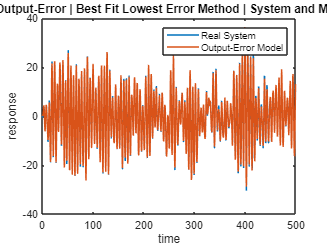

%%
figure(1)
plot(t_val,y3_val,t_val,BestFit_y_hat_3)
legend('Real System','Output-Error Model')
title(" System III : Output-Error | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

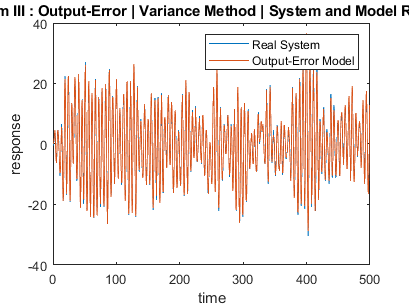


figure(2)
plot(t_val,y3_val,t_val,Var_y_hat_3)
legend('Real System','Output-Error Model')
title(" System III : Output-Error | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

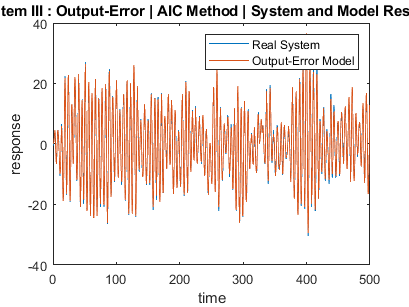


figure(3)
plot(t_val,y3_val,t_val,AIC_y_hat_3)
legend('Real System','Output-Error Model')
title(" System III : Output-Error | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

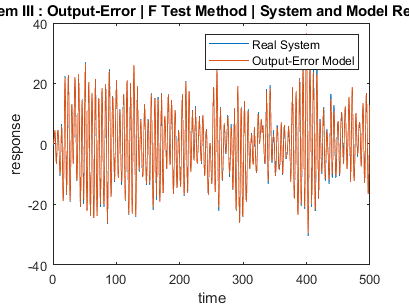


figure(4)
plot(t_val,y3_val,t_val,FTest_y_hat_3)
legend('Real System','Output-Error Model')
title(" System III : Output-Error | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

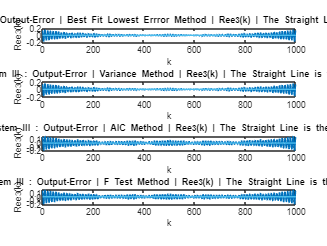

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,oe_BestFit_Ree_3(2:end), 1:N_val-1, mean(oe_BestFit_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | Best Fit Lowest Errror Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,2)
plot(1:N_val-1,oe_Var_Ree_3(2:end), 1:N_val-1, mean(oe_Var_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | Variance Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,3)
plot(1:N_val-1,oe_AIC_Ree_3(2:end), 1:N_val-1, mean(oe_AIC_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | AIC Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,4)
plot(1:N_val-1,oe_FTest_Ree_3(2:end), 1:N_val-1, mean(oe_FTest_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | F Test Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

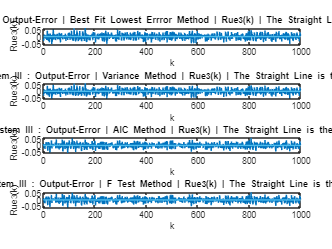

%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,oe_BestFit_Rue_3(2:end), 1:N_val-1, mean(oe_BestFit_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | Best Fit Lowest Errror Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,2)
plot(1:N_val-1,oe_Var_Rue_3(2:end), 1:N_val-1, mean(oe_Var_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | Variance Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,3)
plot(1:N_val-1,oe_AIC_Rue_3(2:end), 1:N_val-1, mean(oe_AIC_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | AIC Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,4)
plot(1:N_val-1,oe_FTest_Rue_3(2:end), 1:N_val-1, mean(oe_FTest_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Output-Error | F Test Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")